syms s
syms h1 h2 real
A=[0 1;-6 -5];
b=[0;1];
c=[1 0];
x0=[1;0];%初期状態
xh0=[0;0];%オブザーバ初期値
h=[h1;h2];

%オブザーバの特性多項式
det(s*eye(2)-(A-h*c))

$$ans = 5\,h_{1}+h_{2}+5\,s+h_{1}\,s+s^{2}+6$$

coeffs(det(s*eye(2)-(A-h*c)),s)

$$ans = \left(\begin{array}{ccc} 5\,h_{1}+h_{2}+6 & h_{1}+5 & 1 \end{array}\right)$$


%オブザーバの極を-2,-2としたときの望みの特性多項式
coeffs((s+2)*(s+2),s)

$$ans = \left(\begin{array}{ccc} 4 & 4 & 1 \end{array}\right)$$

%シミュレーション
h=[-1;3];
eig(A-h*c)

ans =    -2.0000
   -2.0000


X0=[1;-1;1;0]

X0 =      1
    -1
     1
     0


AA=[A zeros(2);h*c A-h*c]

AA =      0     1     0     0
    -6    -5     0     0
    -1     0     1     1
     3     0    -9    -5


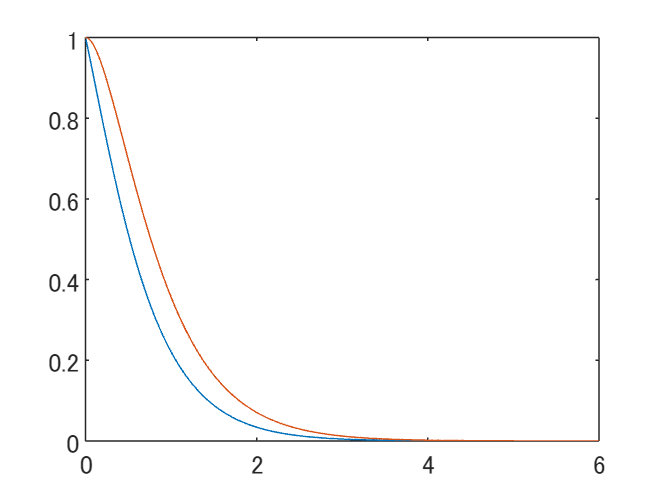

BB=[b;b];
u=0;
[T,X]=ode45(@(t,X) AA*X+BB*u,0:0.01:6,X0);
plot(T,X(:,1),T,X(:,3))

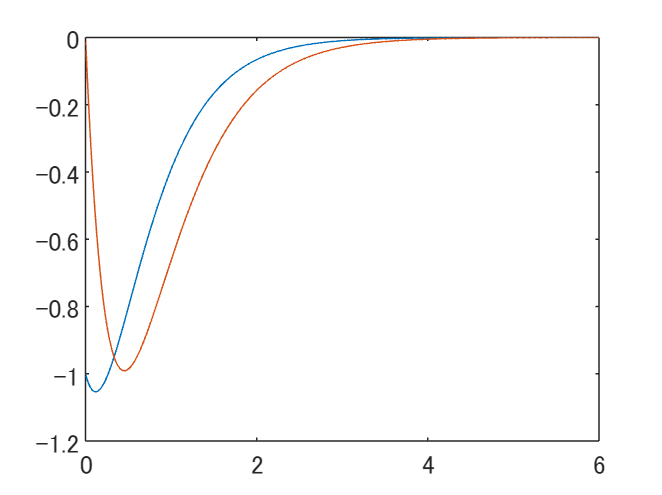

plot(T,X(:,2),T,X(:,4))

%グラフ　青色が真値　黄色がオブザーバ

%双対システムver
h=[-1;3];
F=place(A',c',[-5,-6]);
h=F'

h =      6
    -6


eig(A-h*c)

ans =     -6
    -5


X0=[1;-1;1;0]

X0 =      1
    -1
     1
     0


AA=[A zeros(2);h*c A-h*c]

AA =      0     1     0     0
    -6    -5     0     0
     6     0    -6     1
    -6     0     0    -5


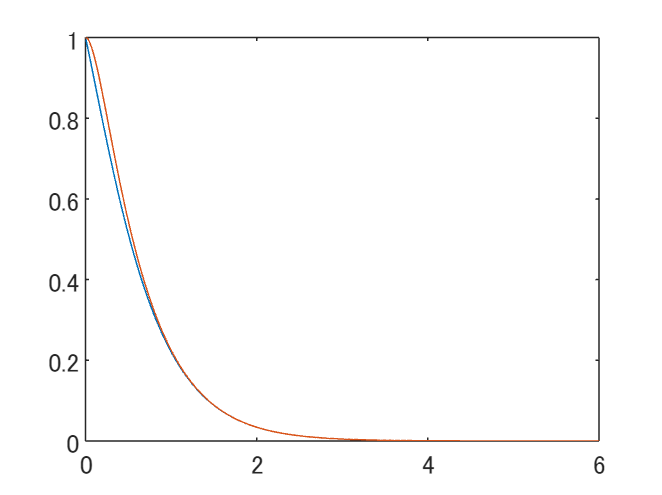

BB=[b;b];
u=0;
[T,X]=ode45(@(t,X) AA*X+BB*u,0:0.01:6,X0);
plot(T,X(:,1),T,X(:,3))

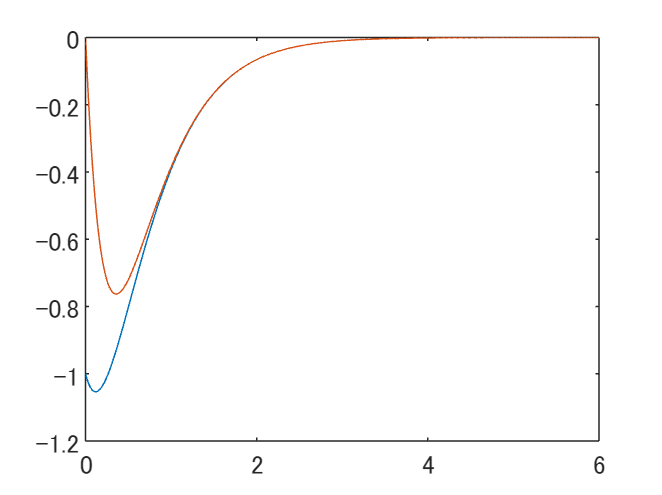

plot(T,X(:,2),T,X(:,4))